# Owen Rogg Personal Project 3

%{
Made by Owen Rogg on April 22, 2026
Personal Project #3

Vehicle Service Checker

%}

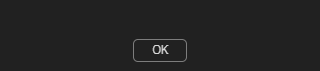

%clear everything for fresh start
clear
clc
close all
%ask for the car's mileage
mileask= inputdlg('What is the lifetime mileage of the vehicle?');
%convert to useable number
mile=str2num(mileask{1});
%ask for driving habits
driveask=inputdlg('Roughly how many miles do you drive daily?');
%convert
drive=str2num(driveask{1});
%set up menu asking which service type
servicetype= menu('Which service?','Oil','Brakes','Transmission');
switch servicetype
    case 1 
        %ask for days since the last oil change, if it exceeds the
        %parameters alert the user.
        oilask=inputdlg('About how many days since the last oil change?');
        oil=str2num(oilask{1});
        milelastoil=(drive*oil);

        differenceoil = abs(6000-milelastoil);
       
        if milelastoil > 6000
            msgbox({['Oil change required! overdue by',num2str(differenceoil),' miles.']},'Service Reminder');
        else
            msgbox({['No oil change needed yet. Still have ',num2str(differenceoil), ' miles left.']},'Service Reminder');
        end
    case 2
        %Ask for days since last brake check, if it exceeds the parameters
        %alert the user.
        brakeask=inputdlg('About how many days since the last brake check?');
        brake=str2num(brakeask{1});
        milelastbrake=(drive*brake);
        differencebrake=abs(30000-milelastbrake);
        if milelastbrake > 30000
            msgbox({['Brake service required! overdue by',num2str(differencebrake),' miles.']},'Service Reminder');
        else
            msgbox({['No brake change needed yet. Still have ',num2str(differencebrake), ' miles left.']},'Service Reminder');
        end
    case 3
        %Ask for days since last transmission service, if it exceeds
        %parameters alert user.
        transask=inputdlg('About how many days since the last transmission service?');
        trans=str2num(transask{1});
        milelasttrans=abs(drive*trans);
        differencetrans=abs(70000-milelasttrans);
        if milelasttrans > 70000
             msgbox({['Transmission service required! overdue by',num2str(differencetrans),' miles.']},'Service Reminder');
        else
            msgbox({['No transmission service needed yet. Still have ',num2str(differencetrans), ' miles left.']},'Service Reminder');
        end
end 